clear all; close all; clc;
tic;
h5disp("gammaray_lab4.h5")

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data')

mydata = 	1.0e+08 *

    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000


mydata(1,:)

ans =    940680016         315          45          10


num = length(mydata(:,1))

num = 25920001

## Problem 1

*In this problem we are looking at the data from a gamma-ray satellite orbiting in low Earth orbit. It takes a reading of the number of particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays.*

*As with most data, there are 'features.' Your lab instructor has helpfully incorporated the meta-data into your data file.*

*1) Down load the data from the course website (gammaray_lab4.h5), and import it into your working environment. The data has 4 columns and more than 25 million rows. The columns are time (in gps seconds), Solar phase (deg) showing the position of the sun relative to the orbit, Earth longitude (deg) giving the position of the spacecraft relative to the ground, and particle counts. Make a few plots, generally exploring your data and making sure you understand it. Give a high level description of the data features you see. Specifically comment on whether you see signal contamination in your data, and how you plan to build a background pdf().*

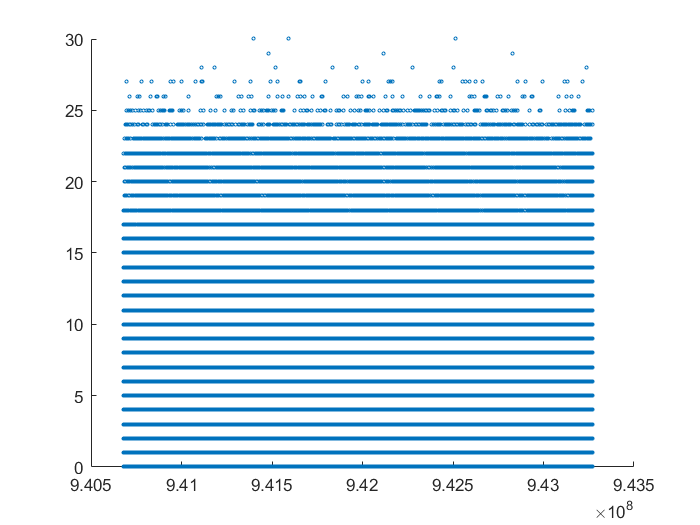

scatter(mydata(:,1),mydata(:,4),4) %gps seconds vs particle counts

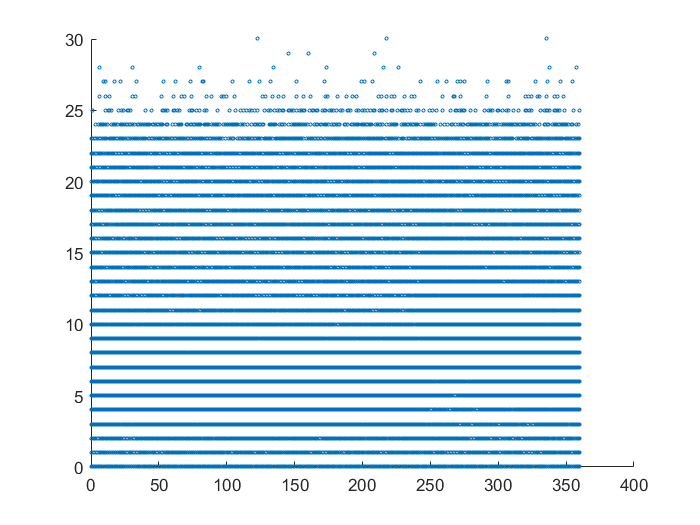

scatter(mydata(:,2),mydata(:,4),4) %Solar phase position vs particle counts

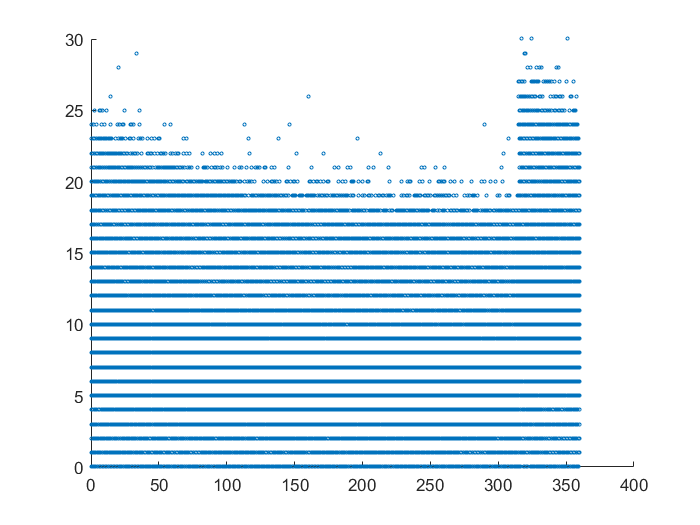

scatter(mydata(:,3),mydata(:,4),4) %Earth Longitude vs particle counts

Possible signal contamination in the last graph of earth longitude vs particle counts

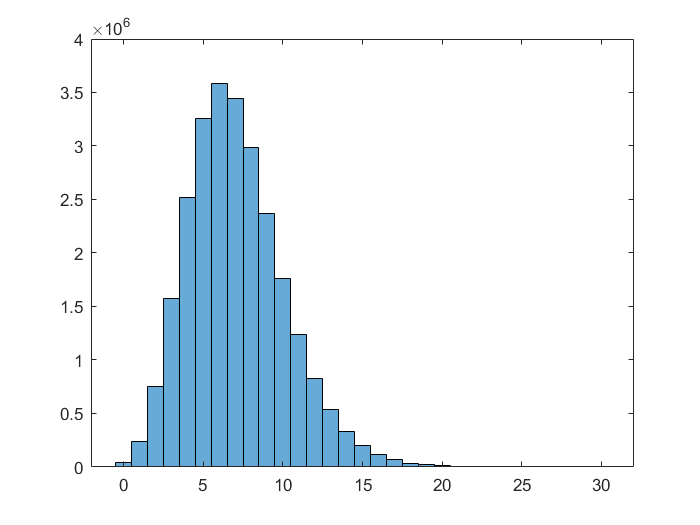

histogram(mydata(:,4))

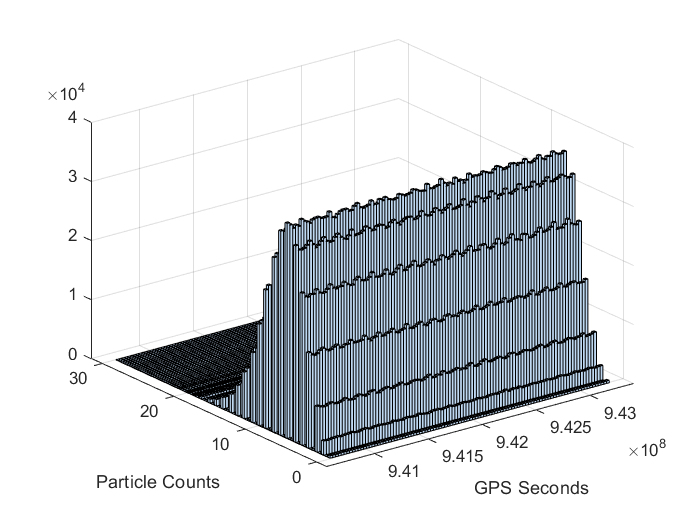

hist3([mydata(:,1),mydata(:,4)],[100,100])
xlabel('GPS Seconds'); ylabel('Particle Counts');

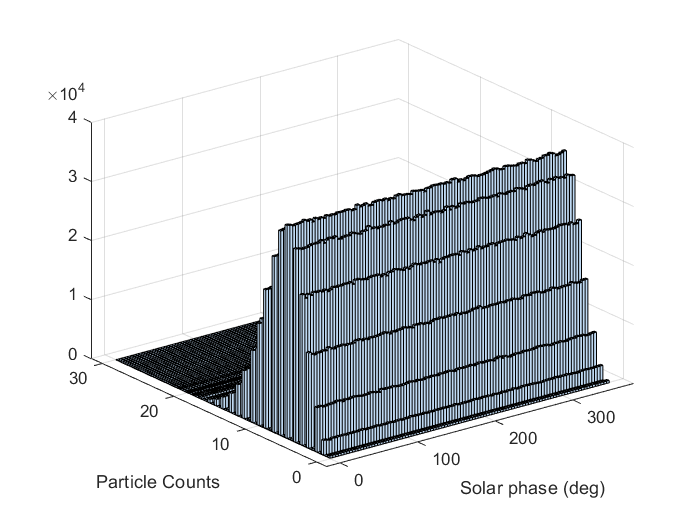

hist3([mydata(:,2),mydata(:,4)],[100,100])
xlabel('Solar phase (deg)'); ylabel('Particle Counts');

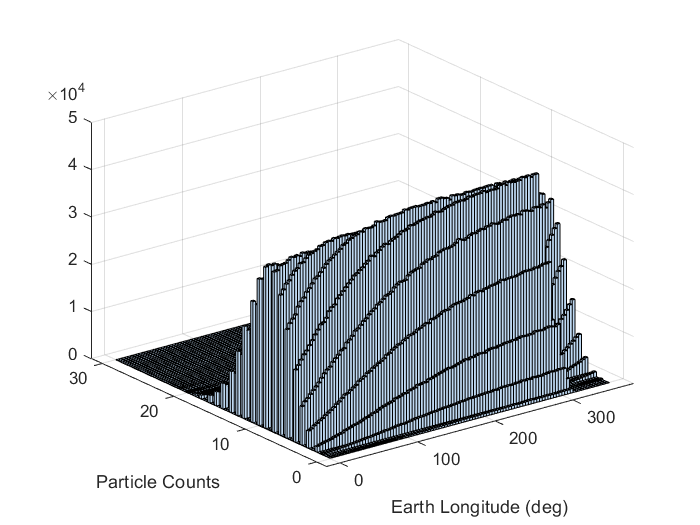

hist3([mydata(:,3),mydata(:,4)],[100,100])
xlabel('Earth Longitude (deg)'); ylabel('Particle Counts');

They all look like a Poisson distribution.

*2) The background is ****not**** consistent across the dataset. Find and describe as accurately as you can how the background changes.*

    The background appears to be consistent across all data sets except for the data set with Earth's Longitude as the independant variable. The Earth Longitude vs particle counts 2D histogram shows a steady decay and then a drastic spike upwards in the particle counts. To look further into this, I created a 3D histogram of all the plots and noticed that the part of the graph where the earth longitude was larger than about 300 degrees had an increase in particle counts by about 5.

*3) Create a model for the background that includes time dependence, and explicitly compare your model to the data. How good is your model of the background?*

The distribution of the data is a poisson distribution so the model must also be of the same distribution. 

    $P(c)=\frac{\lambda ^ce^{-\lambda }}{c!}$ where $\lambda (\theta)$ is a function of the Earth's longitudinal data, $ \lambda (\theta )=C_0e^{-c\theta }$

We notice in the Earth longitude that an exponential decay occurs if the counts decrease proportionally to their current value.


$$\frac{d(\text{Counts})}{d\text{(longitude)}}=-\lambda\times \text{Counts}$$


Solving this equation yields:


$$\text{Counts}(longitude)=\text{Counts}_0\times e^{(-\lambda \times longitude)}$$



$$C(l)=C_0e^{-\lambda l}$$


Need to find a value for $\lambda$, the exponential decay constant, and for $C_0$ to complete this model.

%Max particle count
Max = max(mydata(:,4))

Max = 30

Min = min(mydata(:,4))

Min = 0

%we find that the max number of counts is 30

c1 = mydata(10,4)

c1 = 8

l1 = mydata(10,3)

l1 = 45.0600

RE = range(mydata(:,3))

RE = 359.9933


$$C=C_0e^{-\lambda l}$$



$$\ln{\frac {C}{C_0}}=-\lambda l$$



$$\lambda=-\frac1l \ln{\frac{C}{C_0}}$$


lamb = -(1/45)*log(8/30)

lamb = 0.0294


$$\lambda=-\frac{1}{45} \ln{\frac{8}{30}}=0.0294$$


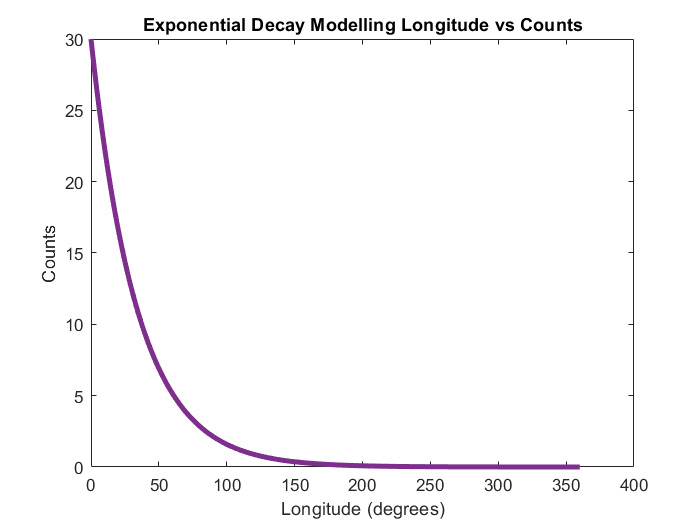

t = mydata(:,1);
l = [0:.5:360];
X = 0.02937*l;
C = 30*exp(-X);
plot(l,C,'LineWidth',3,"Color", [0.4940 0.1840 0.5560])
title("Exponential Decay Modelling Longitude vs Counts")
xlabel("Longitude (degrees)");ylabel("Counts")

For C(t):

t1 = mydata(10:1)


$$C(t)=C_0e^{-\lambda t}$$



$$C_1=C_0e^{-\lambda t_1}$$



$$\ln{\frac {C_1}{C_0}}=-\lambda t_1$$



$$\lambda=-\frac1t_1 \ln{\frac{C_1}{C_0}}$$



$$\lambda=-\frac{1}{t} \ln{\frac{C_1}{C_0}}$$


*4) Because the background varies, your discovery sensitivity threshold (how many particles you would need to see) also varies. What is the '5-sigma' threshold for a 100 millisecond GRB at different times?*

Every 100 ms GRB can be considered to be a "trial" in this case, and we have an orbit every 90 minutes. 

orbitTimeMS = (90*60)/0.001

orbitTimeMS = 5400000

trials = orbitTimeMS/100

trials = 54000

In 90 minutes, we experience 5,400,000ms which equates to 54,000 trials.

*Optional: while this is simulated data, it is based on a real effect seen by low Earth orbit satellites. Can you identify the cause of the variable background and propose a physical model?*

## Problem 2

*In this problem we are going to look at a stack of telescope images (again simulated). We have 10 images, but you and your lab partner will be looking for different signals. One of you will be looking for the faintest stars, while the other will be looking for a transient (something like a super novae that only appears in one image). Flip a coin to determine which of you is pursuing which question.*

*1) Dowload the data from *`images.h5`*. This is a stack of 10 square images, each 200 pixels on a side.*

h5disp("images.h5")

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata2 = h5read("images.h5",'/image1')

mydata2 =    -1.2471    0.0973    0.3390    0.2956    1.9137    0.0763    0.0399   -0.2558   -0.2229   -0.6511   -0.0140    0.7083   -0.0971   -0.3048   -0.4756    0.2987   -0.3554   -0.1238   -0.4046    0.0768   -0.2543    0.0392   -0.5456   -0.2663    0.0707   -0.1318   -0.1836   -0.1499   -0.2999    1.3753   -0.1948   -0.3696    0.4855   -0.6753   -0.6463    0.8828   -0.1690   -0.4287   -0.0287    0.4352    0.2435    1.1049   -0.3340    0.5125    0.9015    0.9251   -0.8317    0.4504    1.1618   -0.8016
   -0.1862    0.2093   -0.2121    0.1595    0.3908    0.3444   -0.1808    0.1337   -0.6025   -0.7623   -1.2264    0.3423   -0.0047    0.0077    1.0298   -0.2821    0.8016    0.1661    0.1519    0.2972    0.7114   -1.2684    0.4984    1.4354    9.7868    0.8268    0.7253   -0.0198   -0.6433    0.2123   -0.0471    0.3807   -0.1384    0.4877   -0.4924   -0.7346   46.8432    0.1063    0.1277   -0.1530    0.6081    0.8553    1.0913    0.4684   -0.8077   -0.3758    0.3301    0.3406    0.039

mydata3 = h5read("images.h5",'/imagestack')

mydata3 = mydata3(:,:,1) =

   -0.5049    0.3135    0.7735   -0.8526    0.3117    0.2109    0.8710    1.1809   -0.2430   -1.2276   -0.2997    1.5025    1.3085    0.2758   -0.0513    0.0964   -0.0627   -0.2774   -0.0143    0.9726    0.3614    0.5823    0.3794    0.7859    0.3061    1.0566    0.1774   -0.1467   -0.0073   -0.4464    1.0458   -0.7855    0.4475   -0.4512   -0.7697   -0.7025   -0.3926    0.6991   -0.2304   -0.3825   -0.5910   -0.2316   -0.3931   -0.5077    0.1902    0.2240    0.5676    0.1382    0.6729   -0.8276    1.5569   -0.5279   -0.1440   -0.1078    0.7901   -0.0169    0.1239    0.5157    0.6278   -0.1588    0.0264    0.0858    0.5401    0.4397   -0.6545    0.1221    0.0066    0.5189   -0.1611    0.1068    0.1726   -0.0727    0.4307   -0.3206    0.4382    0.4710   -0.8132   -0.3321   -0.7933    0.3361   -0.9149    0.3352   -0.9030    0.5075   -0.0296    0.7144   -0.7490   -0.5916   -0.0846   -0.5246   -0.5003    0.2628   -0.4636   -0.2944   -0.1406   -0.4980    0.1965  

*2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf().*

*3) Using your background distribution, hunt for your signal (either faint stars, or a transient). Describe what you find.*

*4) You and your lab partner had different pdf(), but were using the same data. Explore why this is.*

toc;

Elapsed time is 141.772386 seconds.
